## Gurobi: general Pareto front and time benchmarking

### Uniform weights, step 0.1, alpha=25 (penalty factor)

% Span for uniform weights
span = 0.01:0.02:0.99;

% Placeholders for costs and runtimes
cost_gurobi = zeros(length(span), 2);
runtime_gurobi = zeros(1, length(span));
cost_sedumi = zeros(length(span), 2);
runtime_sedumi = zeros(1, length(span));

% Penalty
alpha = 25;

% Load the network into the workspace

% NOTE: Sometimes the problem is infeasible due to demand
% and starting state mismatch. Don't have enough time to fix it rn
% so you'll sometimes have to run the network_init function a couple of times.

network = network_init(3, 5);

% Run computations for one network, different weights

for i = 1:length(span)
    w2 = span(i);
    w1 = 1 - w2;
    network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
    network.Q_biobj = network.Q * w1;
    result_gurobi = solve_gurobi(network);
    [cost_gurobi(i, 1), cost_gurobi(i, 2)] = objective_values(network, alpha, result_gurobi.x);
    runtime_gurobi(i) = result_gurobi.runtime;

    [result_sedumi, runtime_sedumi(i)] = solve_sedumi(network);
    [cost_sedumi(i, 1), cost_sedumi(i, 2)] = objective_values(network, alpha, result_sedumi);
end

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 230 rows, 85 columns and 377 nonzeros
Model fingerprint: 0x3b7e5d4a
Model has 15 quadratic objective terms
Variable types: 35 continuous, 50 integer (50 binary)
Coefficient statistics:
  Matrix range     [1e+00, 2e+02]
  Objective range  [1e-02, 2e+03]
  QObjective range [2e-03, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 3e+02]
Found heuristic solution: objective 4.950000e+11
Presolve removed 211 rows and 56 columns
Presolve time: 0.05s
Presolved: 19 rows, 29 columns, 49 nonzeros
Presolved model has 10 quadratic objective terms
Found heuristic solution: objective 33182.000641
Variable types: 14 continuous, 15 integer (15 binary)
Found heur

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3741, order n = 319, dim = 7629, blocks = 3
nnz(A) = 4119 + 0, nnz(ADA) = 13995081, nnz(L) = 6999411
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.27E-03 0.000
  1 :   4.73E+04 7.56E-04 0.000 0.5972 0.9000 0.9000   1.34  1  1  3.4E+02
  2 :  -1.38E+04 3.02E-04 0.000 0.3986 0.9000 0.9000   1.50  1  1  1.2E+02
  3 :  -5.19E+04 1.43E-04 0.000 0.4742 0.9000 0.9000   1.20  1  1  5.1E+01
  4 :  -6.47E+04 6.90E-05 0.000 0.4823 0.9000 0.9000   0.94  1  1  2.6E+01
  5 :  -6.02E+04 3.62E-05 0.000 0.5245 0.9000 0.9000   0.90  1  1  1.3E+01
  6 :  -5.93E+04 1.79E-05 0.000 0.4950 0.9000 0.9000   0.56  1  1  7.9E+00
  7 :  -5.15E+04 1.10E-05 0.000 0.6159 0.9000 0.9000   0.96  1  1  4.3E+00
  8 :  -4.97E+04 4.88E-06 0.000 0.4424 0.9000 0.9000   0.59  1  1  2.5E+00
  9 :  -4.54E+04 3.40E-06 0.000 0.6978 0.9000 0.9000   1.09  1  1  1.5E+0

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 230 rows, 85 columns and 377 nonzeros
Model fingerprint: 0xf32f6ad4
Model has 15 quadratic objective terms
Variable types: 35 continuous, 50 integer (50 binary)
Coefficient statistics:
  Matrix range     [1e+00, 2e+02]
  Objective range  [2e-02, 2e+03]
  QObjective range [2e-03, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 3e+02]
Found heuristic solution: objective 4.850000e+11
Presolve removed 211 rows and 56 columns
Presolve time: 0.01s
Presolved: 19 rows, 29 columns, 49 nonzeros
Presolved model has 10 quadratic objective terms
Found heuristic solution: objective 32529.742715
Variable types: 14 continuous, 15 integer (15 binary)
Found heur

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3741, order n = 319, dim = 7629, blocks = 3
nnz(A) = 4119 + 0, nnz(ADA) = 13995081, nnz(L) = 6999411
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.29E-03 0.000
  1 :   4.63E+04 7.72E-04 0.000 0.5972 0.9000 0.9000   1.34  1  1  3.4E+02
  2 :  -1.36E+04 3.08E-04 0.000 0.3986 0.9000 0.9000   1.50  1  1  1.2E+02
  3 :  -5.09E+04 1.46E-04 0.000 0.4742 0.9000 0.9000   1.20  1  1  5.1E+01
  4 :  -6.35E+04 7.04E-05 0.000 0.4823 0.9000 0.9000   0.94  1  1  2.6E+01
  5 :  -5.90E+04 3.69E-05 0.000 0.5245 0.9000 0.9000   0.90  1  1  1.3E+01
  6 :  -5.81E+04 1.83E-05 0.000 0.4950 0.9000 0.9000   0.56  1  1  7.9E+00
  7 :  -5.05E+04 1.13E-05 0.000 0.6159 0.9000 0.9000   0.96  1  1  4.3E+00
  8 :  -4.87E+04 4.98E-06 0.000 0.4424 0.9000 0.9000   0.59  1  1  2.5E+00
  9 :  -4.45E+04 3.47E-06 0.000 0.6978 0.9000 0.9000   1.09  1  1  1.5E+0

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 230 rows, 85 columns and 377 nonzeros
Model fingerprint: 0x5c32a743
Model has 15 quadratic objective terms
Variable types: 35 continuous, 50 integer (50 binary)
Coefficient statistics:
  Matrix range     [1e+00, 2e+02]
  Objective range  [2e-02, 2e+03]
  QObjective range [2e-03, 8e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 3e+02]
Found heuristic solution: objective 4.750000e+11
Presolve removed 211 rows and 56 columns
Presolve time: 0.01s
Presolved: 19 rows, 29 columns, 49 nonzeros
Presolved model has 10 quadratic objective terms
Found heuristic solution: objective 31877.484789
Variable types: 14 continuous, 15 integer (15 binary)
Found heur

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3741, order n = 319, dim = 7629, blocks = 3
nnz(A) = 4119 + 0, nnz(ADA) = 13995081, nnz(L) = 6999411
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.32E-03 0.000
  1 :   4.54E+04 7.88E-04 0.000 0.5972 0.9000 0.9000   1.34  1  1  3.4E+02
  2 :  -1.33E+04 3.14E-04 0.000 0.3986 0.9000 0.9000   1.50  1  1  1.2E+02
  3 :  -4.99E+04 1.49E-04 0.000 0.4742 0.9000 0.9000   1.20  1  1  5.1E+01
  4 :  -6.22E+04 7.19E-05 0.000 0.4823 0.9000 0.9000   0.94  1  1  2.6E+01
  5 :  -5.78E+04 3.77E-05 0.000 0.5245 0.9000 0.9000   0.90  1  1  1.3E+01
  6 :  -5.69E+04 1.87E-05 0.000 0.4950 0.9000 0.9000   0.56  1  1  7.9E+00
  7 :  -4.94E+04 1.15E-05 0.000 0.6159 0.9000 0.9000   0.96  1  1  4.3E+00
  8 :  -4.77E+04 5.08E-06 0.000 0.4424 0.9000 0.9000   0.59  1  1  2.5E+00
  9 :  -4.36E+04 3.55E-06 0.000 0.6978 0.9000 0.9000   1.09  1  1  1.5E+0

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 230 rows, 85 columns and 377 nonzeros
Model fingerprint: 0xe3d57ba6
Model has 15 quadratic objective terms
Variable types: 35 continuous, 50 integer (50 binary)
Coefficient statistics:
  Matrix range     [1e+00, 2e+02]
  Objective range  [2e-02, 2e+03]
  QObjective range [1e-03, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 3e+02]
Found heuristic solution: objective 4.650000e+11
Presolve removed 211 rows and 56 columns
Presolve time: 0.02s
Presolved: 19 rows, 29 columns, 49 nonzeros
Presolved model has 10 quadratic objective terms
Found heuristic solution: objective 31225.226863
Variable types: 14 continuous, 15 integer (15 binary)
Found heur

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3741, order n = 319, dim = 7629, blocks = 3
nnz(A) = 4119 + 0, nnz(ADA) = 13995081, nnz(L) = 6999411
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.35E-03 0.000
  1 :   4.44E+04 8.05E-04 0.000 0.5972 0.9000 0.9000   1.34  1  1  3.4E+02
  2 :  -1.31E+04 3.21E-04 0.000 0.3986 0.9000 0.9000   1.50  1  1  1.2E+02
  3 :  -4.88E+04 1.52E-04 0.000 0.4742 0.9000 0.9000   1.20  1  1  5.1E+01
  4 :  -6.09E+04 7.34E-05 0.000 0.4823 0.9000 0.9000   0.94  1  1  2.6E+01
  5 :  -5.66E+04 3.85E-05 0.000 0.5245 0.9000 0.9000   0.90  1  1  1.3E+01
  6 :  -5.58E+04 1.91E-05 0.000 0.4950 0.9000 0.9000   0.56  1  1  7.9E+00
  7 :  -4.84E+04 1.17E-05 0.000 0.6159 0.9000 0.9000   0.96  1  1  4.3E+00
  8 :  -4.67E+04 5.19E-06 0.000 0.4424 0.9000 0.9000   0.59  1  1  2.5E+00
  9 :  -4.27E+04 3.62E-06 0.000 0.6978 0.9000 0.9000   1.09  1  1  1.5E+0

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 230 rows, 85 columns and 377 nonzeros
Model fingerprint: 0x0607dd35
Model has 15 quadratic objective terms
Variable types: 35 continuous, 50 integer (50 binary)
Coefficient statistics:
  Matrix range     [1e+00, 2e+02]
  Objective range  [2e-02, 2e+03]
  QObjective range [1e-03, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 3e+02]
Found heuristic solution: objective 4.550000e+11
Presolve removed 211 rows and 56 columns
Presolve time: 0.14s
Presolved: 19 rows, 29 columns, 49 nonzeros
Presolved model has 10 quadratic objective terms
Found heuristic solution: objective 30572.968937
Variable types: 14 continuous, 15 integer (15 binary)
Found heur

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3741, order n = 319, dim = 7629, blocks = 3
nnz(A) = 4119 + 0, nnz(ADA) = 13995081, nnz(L) = 6999411
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.38E-03 0.000
  1 :   4.34E+04 8.23E-04 0.000 0.5972 0.9000 0.9000   1.34  1  1  3.4E+02
  2 :  -1.28E+04 3.28E-04 0.000 0.3986 0.9000 0.9000   1.50  1  1  1.2E+02
  3 :  -4.78E+04 1.56E-04 0.000 0.4742 0.9000 0.9000   1.20  1  1  5.1E+01
  4 :  -5.96E+04 7.50E-05 0.000 0.4823 0.9000 0.9000   0.94  1  1  2.6E+01
  5 :  -5.54E+04 3.93E-05 0.000 0.5245 0.9000 0.9000   0.90  1  1  1.3E+01
  6 :  -5.46E+04 1.95E-05 0.000 0.4950 0.9000 0.9000   0.56  1  1  7.9E+00
  7 :  -4.74E+04 1.20E-05 0.000 0.6159 0.9000 0.9000   0.96  1  1  4.3E+00
  8 :  -4.57E+04 5.31E-06 0.000 0.4424 0.9000 0.9000   0.59  1  1  2.5E+00
  9 :  -4.18E+04 3.70E-06 0.000 0.6978 0.9000 0.9000   1.09  1  1  1.5E+0

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 230 rows, 85 columns and 377 nonzeros
Model fingerprint: 0x8f347f35
Model has 15 quadratic objective terms
Variable types: 35 continuous, 50 integer (50 binary)
Coefficient statistics:
  Matrix range     [1e+00, 2e+02]
  Objective range  [2e-02, 2e+03]
  QObjective range [1e-03, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 3e+02]
Found heuristic solution: objective 4.450000e+11
Presolve removed 211 rows and 56 columns
Presolve time: 0.01s
Presolved: 19 rows, 29 columns, 49 nonzeros
Presolved model has 10 quadratic objective terms
Found heuristic solution: objective 29920.711012
Variable types: 14 continuous, 15 integer (15 binary)
Found heur

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3741, order n = 319, dim = 7629, blocks = 3
nnz(A) = 4119 + 0, nnz(ADA) = 13995081, nnz(L) = 6999411
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.41E-03 0.000
  1 :   4.25E+04 8.41E-04 0.000 0.5972 0.9000 0.9000   1.34  1  1  3.4E+02
  2 :  -1.26E+04 3.35E-04 0.000 0.3986 0.9000 0.9000   1.50  1  1  1.2E+02
  3 :  -4.68E+04 1.59E-04 0.000 0.4742 0.9000 0.9000   1.20  1  1  5.1E+01
  4 :  -5.83E+04 7.67E-05 0.000 0.4823 0.9000 0.9000   0.94  1  1  2.6E+01
  5 :  -5.42E+04 4.02E-05 0.000 0.5245 0.9000 0.9000   0.90  1  1  1.3E+01
  6 :  -5.34E+04 1.99E-05 0.000 0.4950 0.9000 0.9000   0.56  1  1  7.9E+00
  7 :  -4.64E+04 1.23E-05 0.000 0.6159 0.9000 0.9000   0.96  1  1  4.3E+00
  8 :  -4.47E+04 5.43E-06 0.000 0.4424 0.9000 0.9000   0.59  1  1  2.5E+00
  9 :  -4.09E+04 3.79E-06 0.000 0.6978 0.9000 0.9000   1.09  1  1  1.5E+0

gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;


% Tiles for plot
tiledlayout(2,1);

% Pareto front
nexttile
loglog(cost_gurobi(:, 1), cost_gurobi(:, 2), 'o', 'Color', gurobi_color, 'MarkerSize', 3); hold on
loglog(cost_sedumi(:, 1), cost_sedumi(:, 2), 'o', 'Color', sedumi_color, 'MarkerSize', 3); hold off
title('Pareto Frontiers');
legend('Gurobi', 'SeDuMi');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');
% Move to the next plot tile
nexttile
plot(1:1:length(runtime_gurobi), runtime_gurobi, 'Color', gurobi_color); hold on
plot(1:1:length(runtime_sedumi), runtime_sedumi, 'Color', sedumi_color); hold off
title('Runtimes');
legend('Gurobi', 'SeDuMi');
xlabel('$i$', 'Interpreter','latex');
ylabel('$t$, seconds', 'Interpreter','latex');

% Find the biggest gap in the Pareto front
% Euclidian distance
distances = sqrt(diff(cost_gurobi(:, 1)).^2 + diff(cost_gurobi(:, 2)).^2);

% Find the index of the maximum distance
[~, maxdist] = max(distances);

% Find the corresponding values in the span
upper = span(maxdist);
lower = span(maxdist + 1);

% Construct refinement
span_refined = upper:0.0001:lower;

% Placeholder for front refinement
cost_gurobi_refined = zeros(length(span_refined), 2);

% Compute for new span
for i = 1:length(span_refined)
    w2 = span_refined(i);
    w1 = 1 - w2;
    network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
    network.Q_biobj = network.Q * w1;
    result_gurobi = solve_gurobi(network);
    [cost_gurobi_refined(i, 1), cost_gurobi_refined(i, 2)] = objective_values(network, alpha, result_gurobi.x);
end

figure();
loglog(cost_gurobi(:, 1), cost_gurobi(:, 2), 'o', 'Color', gurobi_color, 'MarkerSize', 3); hold on
loglog(cost_gurobi_refined(:, 1), cost_gurobi_refined(:, 2), 'o', 'Color', 'red', 'MarkerSize', 3); hold off
title('Refined Pareto front');
legend('Original', 'Refinement');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');

## Gurobi: influence of penalty

% Span for uniform weights
span_pen = 0.01:0.01:0.999;
% Span for penalties
pens = [0, 25, 250];

% Placeholder variables
cost_gurobi_pen = zeros(length(span), 2);


% Plot graph in process
tiledlayout(length(pens), 1)

% Do a full front for every penalty
for i = 1:length(pens)
    alpha = pens(i);
    for j = 1:length(span_pen)
        w2 = span_pen(j);
        w1 = 1 - w2;
        network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
        network.Q_biobj = network.Q * w1;
        result_gurobi = solve_gurobi(network);
        [cost_gurobi_pen(j, 1), cost_gurobi_pen(j, 2)] = objective_values(network, alpha, result_gurobi.x);
    end  
    nexttile
    loglog(cost_gurobi_pen(:, 1), cost_gurobi_pen(:, 2), 'o', 'MarkerSize', 3)
end

## Wind and solar generation plots (24H)

gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;

x = linspace(1, 24, 24);
wind_power = zeros(1, 24);
solar_power = zeros(1, 24);
for t = 1:24
    wind_power(t) = pdf(t, "wind");
    solar_power(t) = pdf(t, "solar");
end

figure()
plot(x, wind_power, Color=sedumi_color, LineWidth=2); hold on
yline(25.5,'-','Wind forecast');
yline(mean(wind_power),'--','Wind mean', Color=sedumi_color);
plot(x, solar_power, Color=gurobi_color, LineWidth=2); hold off
yline(40,'-','Solar forecast');
yline(mean(solar_power(5:20)),'--','Solar mean (5AM-8PM)', Color=gurobi_color);
title('VRE generation in 24H timespan')
legend('Wind', 'Solar');
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$g$, MW', 'Interpreter','latex');

## Example of network demand

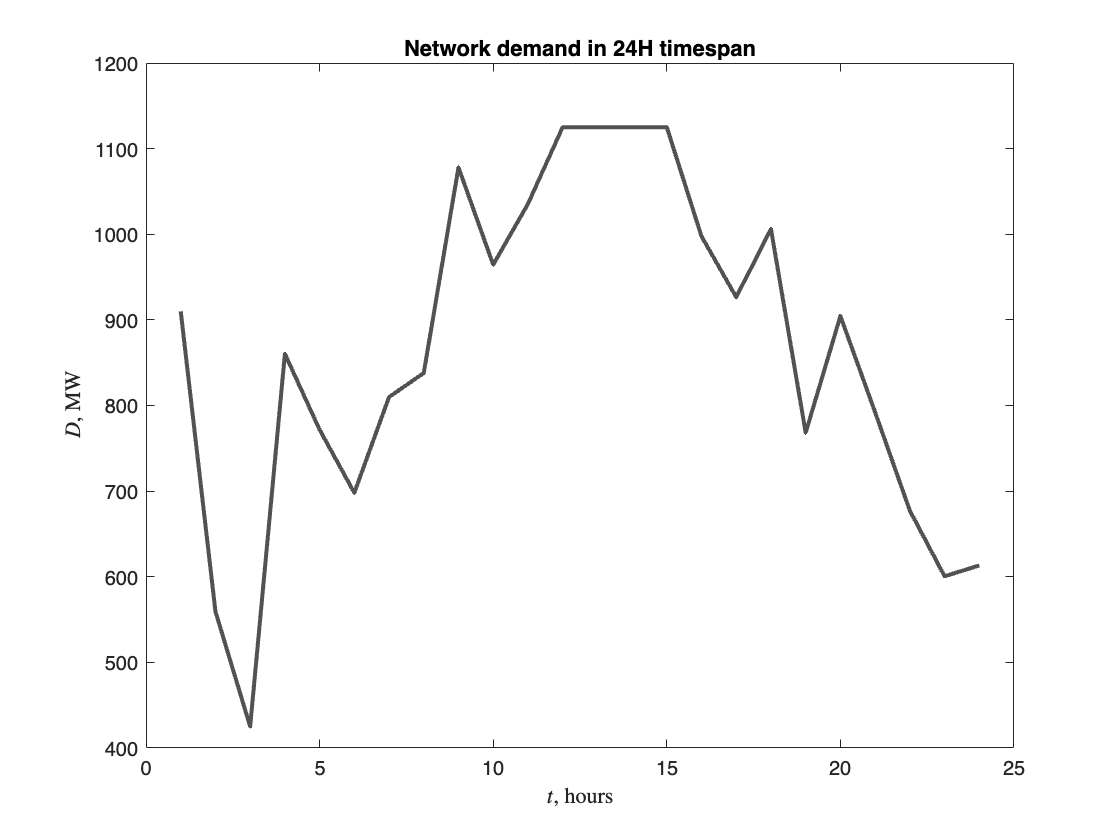

demand_color = [83 81 84]/255;

maxgen = [455, 455, 160, 55];
starting_state = [1, 1, 0, 0];
x = linspace(1, 24, 24);
demand_profile = demand(maxgen, starting_state, 24);

figure()
plot(x, demand_profile, LineWidth=2, Color=demand_color);
title('Network demand in 24H timespan')
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$D$, MW', 'Interpreter','latex');